# **This is question 1 of the MATLAB Assignment**

**1.a The question requires the creation of a custom wave with the given credentials:-**

Smapling frequency = 800 kHz i.e number of time samples to be used are 800,000

sam_freq = 8e005;                   % represented in scientific notation
end_time = 5e-3;                              % Defining 5 ms.
true_sam_freq = sam_freq*end_time;                  % Ambient Sampling frequency
t = linspace(0,end_time, true_sam_freq);  

Frequency is last three digits of my Id. Hence. freq = 507 Hz (My Id is 0507)

f = 1507;

Defining the custom signal

x = zeros(1,true_sam_freq);
for i = 1:true_sam_freq
    if(t(1:i) < 3e-3)
        x(1,i) = 5*cos(2*pi*f*t(1,i));
    else
        x(1,i) = 0;
    end
end

b = 7e-3*(ones(1,true_sam_freq));                     % b is 7 ms.
new_t = t - b;

**1.b **

new_t_b = -2*(t-b);

Plotting the signal

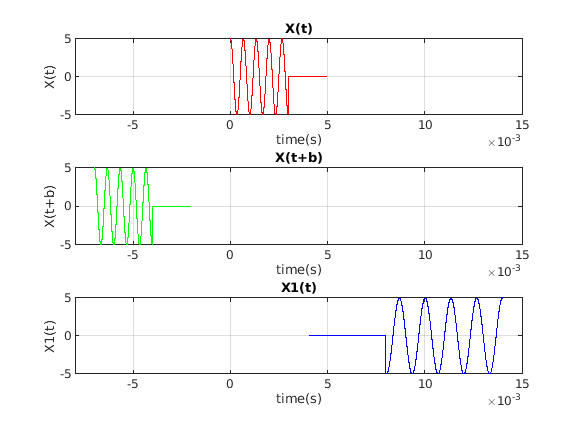

subtitle('Required signals');

subplot(3,1,1),plot(t,x,'r');
title('X(t)');
xlabel('time(s)');
ylabel('X(t)');
axis([-8e-3 15e-3 -5 5]);
grid on;

subplot(3,1,2),plot(new_t,x,'g');
title('X(t+b)');
xlabel('time(s)');
ylabel('X(t+b)');
axis([-8e-3 15e-3 -5 5]);
grid on;

subplot(3,1,3),plot(new_t_b,x,'b');
title('X1(t)');
xlabel('time(s)');
ylabel('X1(t)');
axis([-8e-3 15e-3 -5 5]);
grid on;